# Multiclass classification with neural networks - Handwritten number recognition

In this tutorial you will develop a multi-class classifier to determine the value of handwritten digits between 0 and 9. The MNIST data set is a real world data set, although for this tutorial the data have been cleaned, pre-processed, and scaled. You should solve this problem with an Artificial Neural Network (ANN) and perform the weight training with conjugate gradient descent.

## Set up Environment

clc, clear, close all
addpath('lib')
addpath('Data')

## Load Number Data

We will now use the MNIST data set as an example problem.

***Note that:***** the digits between 1 and 9 match up with the class number, whereas the digit 0 corresponds to class 10.**

load('digit_database.mat');
[n, m] = size(X);
ny = length(unique(y));

Training data characteristics.

fprintf('Size of the training data set is: [%i, %i]', n, m)

Size of the training data set is: [5000, 400]

for i = 1:ny
    fprintf('Number of instances of class %2i is:  %i\n', i, sum(y==i))
end

Number of instances of class  1 is:  500
Number of instances of class  2 is:  500
Number of instances of class  3 is:  500
Number of instances of class  4 is:  500
Number of instances of class  5 is:  500
Number of instances of class  6 is:  500
Number of instances of class  7 is:  500
Number of instances of class  8 is:  500
Number of instances of class  9 is:  500
Number of instances of class 10 is:  500


## Data Visulisation

Run this section many times to have a look at the data.

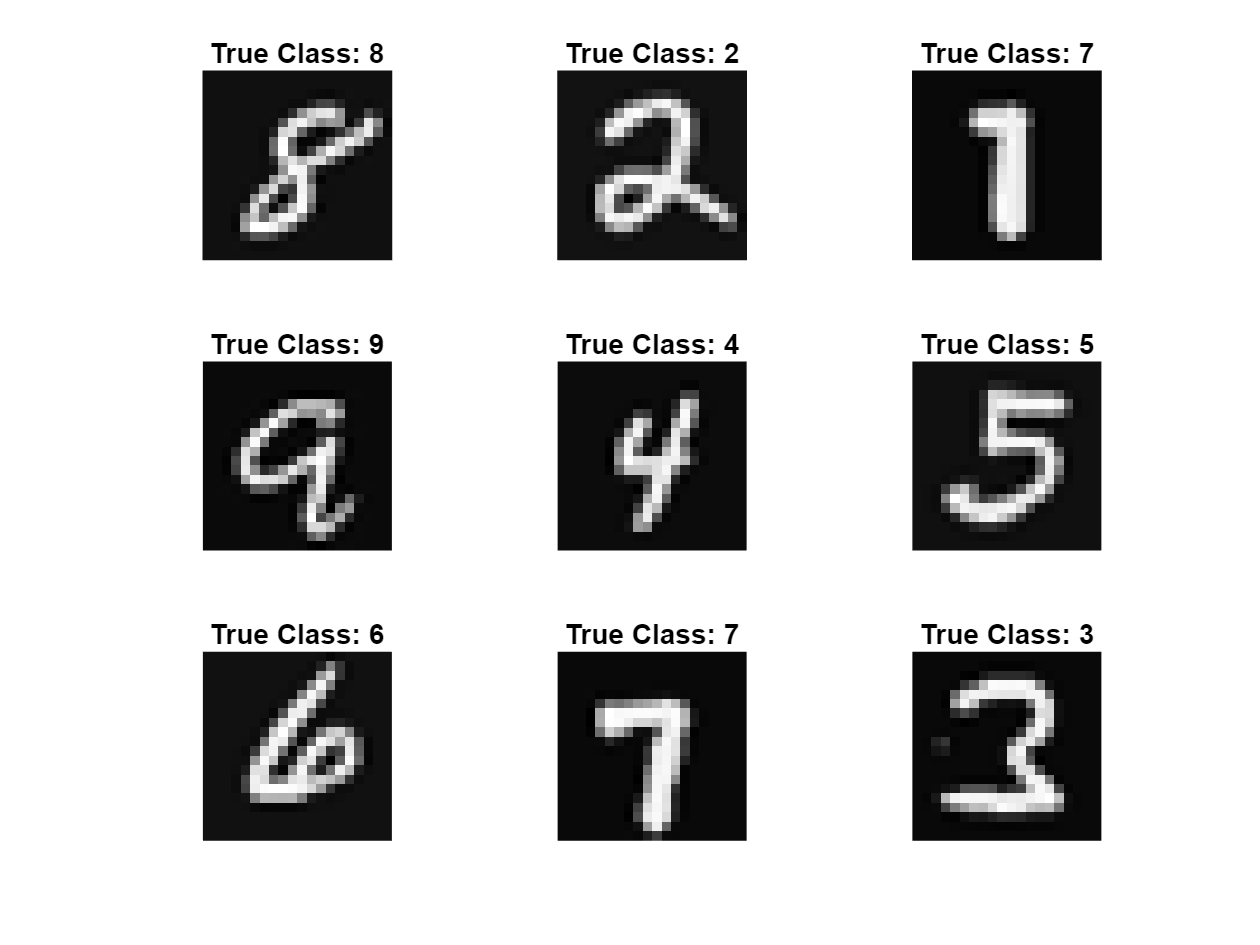

figure, hold on, box on
tiledlayout(3, 3)
for t = 1:9
    nexttile
    i = randi(n);
    im = reshape(X(i, :), sqrt(m), sqrt(m)); % 24 x 24 pixel images
    imagesc(im);
    colormap('gray');
    axis image off
    title(sprintf('True Class: %i', y(i)))
end

## **Model Development**

**Example cost function convergency**

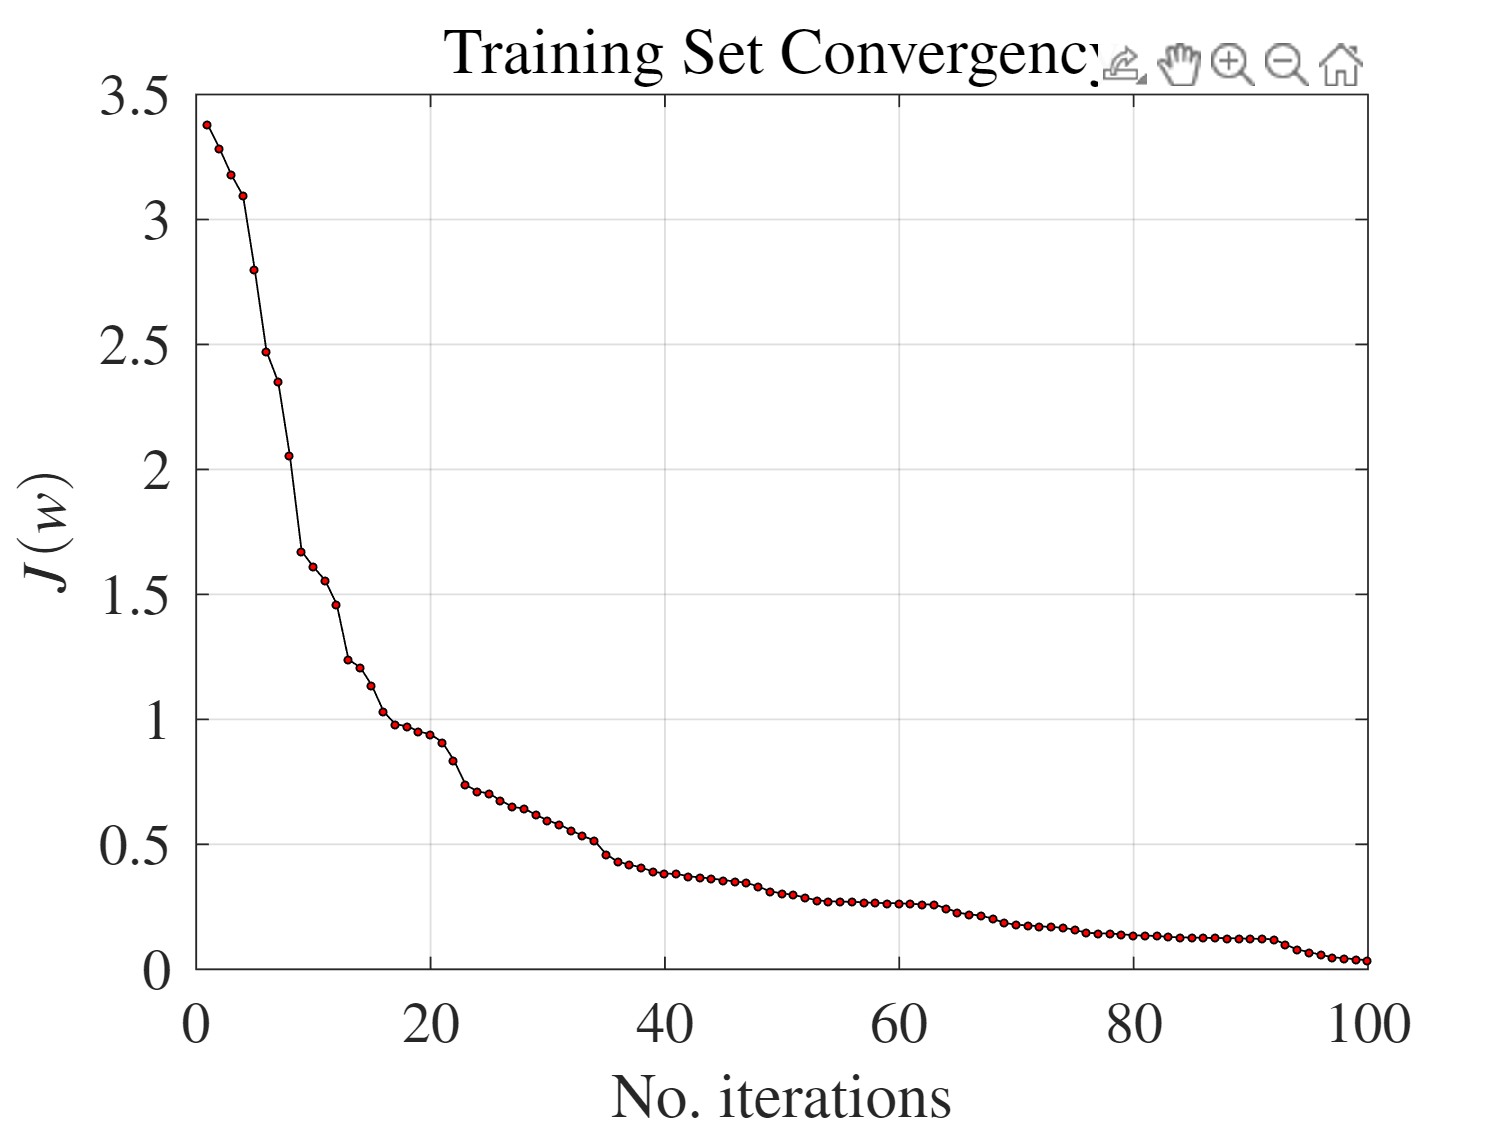

fprintf('\nExample Training Set Accuracy:\t %f\n', 99.97);


Example Training Set Accuracy:	 99.970000


## Model Accuracy on testing set

fprintf('\nExample Testing Set Accuracy:\t %f\n', 94.00);


Example Testing Set Accuracy:	 94.000000


fprintf('\nExample Confusion Matrix:\t%3i %3i %3i %3i %3i %3i %3i %3i %3i %3i\n\t\t\t\t%3i %3i %3i %3i %3i %3i %3i %3i %3i %3i\n\t\t\t\t%3i %3i %3i %3i %3i %3i %3i %3i %3i %3i\n\t\t\t\t%3i %3i %3i %3i %3i %3i %3i %3i %3i %3i\n\t\t\t\t%3i %3i %3i %3i %3i %3i %3i %3i %3i %3i\n\t\t\t\t%3i %3i %3i %3i %3i %3i %3i %3i %3i %3i\n\t\t\t\t%3i %3i %3i %3i %3i %3i %3i %3i %3i %3i\n\t\t\t\t%3i %3i %3i %3i %3i %3i %3i %3i %3i %3i\n\t\t\t\t%3i %3i %3i %3i %3i %3i %3i %3i %3i %3i\n\t\t\t\t%3i %3i %3i %3i %3i %3i %3i %3i %3i %3i', ...
    136, 0, 0, 0, 0, 0, 1, 0, 0, 0, 1, 141, 0, 1, 0, 1, 0, 2, 0, 0, 0, 2, 157, 0, 11, 0, 0, 2, 1, 2, 0, 2, 0, 118, 0, 1, 3, 1, 2, 0, 0, 1, 3, 0, 125, 2, 0, 4, 1, 0, 0, 0, 1, 2, 1, 152, 0, 0, 0, 0, 2, 2, 2, 0, 0, 0, 150, 0, 4, 0, 2, 3, 1, 1, 1, 1, 2, 119, 2, 0, 0, 0, 2, 2, 4, 0, 4, 0, 157, 1, 0, 2, 0, 0, 0, 0, 2, 1, 1, 155.00);


Example Confusion Matrix:	136   0   0   0   0   0   1   0   0   0
				  1 141   0   1   0   1   0   2   0   0
				  0   2 157   0  11   0   0   2   1   2
				  0   2   0 118   0   1   3   1   2   0
				  0   1   3   0 125   2   0   4   1   0
				  0   0   1   2   1 152   0   0   0   0
				  2   2   2   0   0   0 150   0   4   0
				  2   3   1   1   1   1   2 119   2   0
				  0   0   2   2   4   0   4   0 157   1
				  0   2   0   0   0   0   2   1   1 155

## Performance Check

**Example performance on correctly classified data**

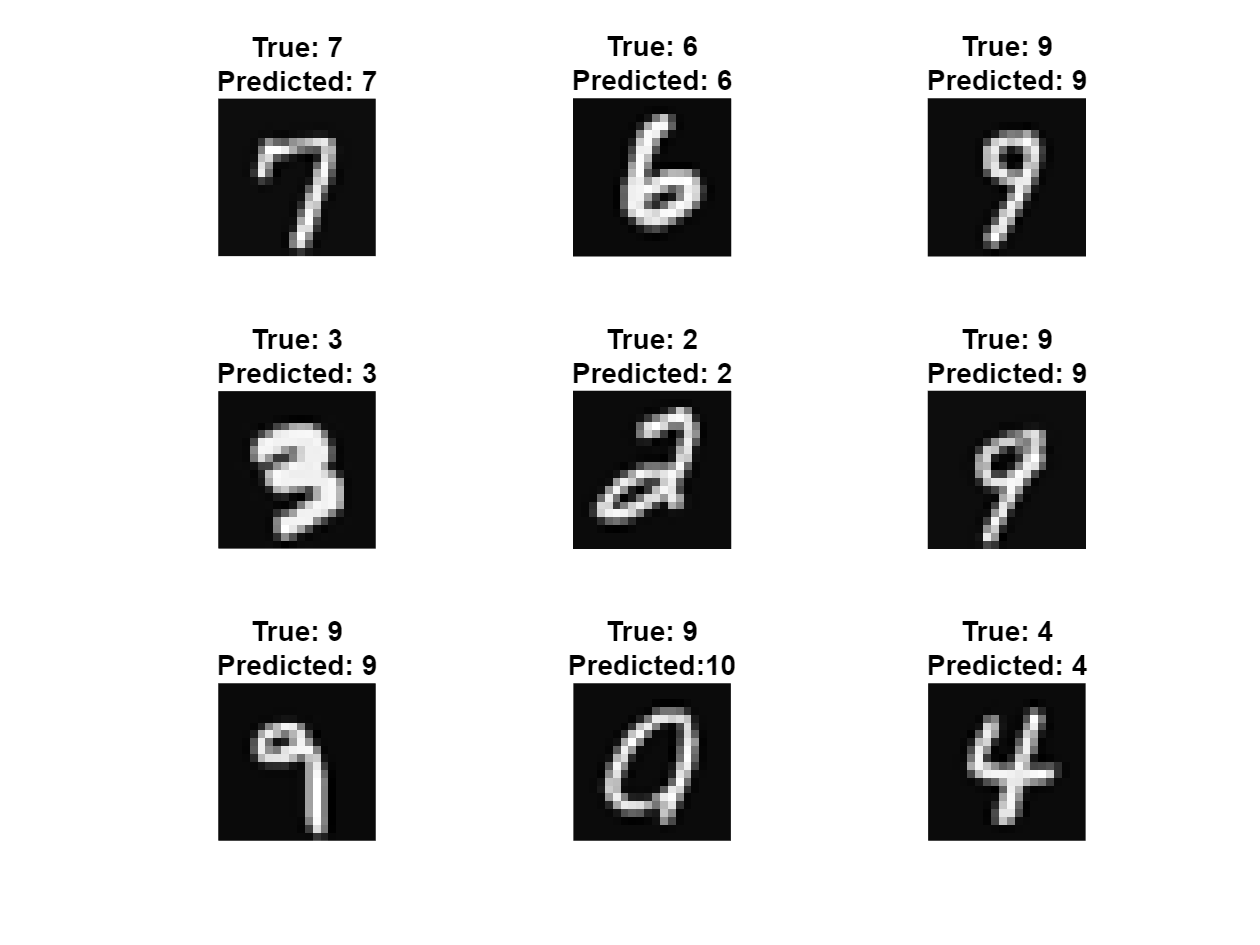

## Incorrectly Classified

**Example performance on incorrectly classified data**